# **Synchrony analysis**

**Clear the workspace**

clearvars -except folderNames dataFolders

## Import Data and Extract Behavioral Interval of Interest

events_import = readmatrix("detected_events.xlsx"); %Import events data from Excel spreadsheet
events = events_import(any(events_import,2),:); %removes the rows with all zero, to remove the cells without any detected event during the time interval

Inactivate this section when following the data analysis workfow (ctrl+R to inactivate; ctrl+T to activate)

% start_time = 1; % put the interval of interest, unit is second
% end_time = 130;
% 
% % still need fix this part--need it no decimal
% % Extract from events matrix the behavioral interval of interest; 65.6 ms/frame

Inactivate this section when want to do manually input

start_time = readmatrix ("start_time.xlsx");
end_time = readmatrix ("end_time.xlsx");

Apply time interval to data

Events_extracted = events(:,floor(start_time/0.0656):floor(end_time/0.0656) - 1);

## Converting matrix to binary for detected event

Event_extracted_binary = logical(Events_extracted);
synchrony = sum(Event_extracted_binary);
cell_number = size(Events_extracted,1);
synchrony_fraction = synchrony / cell_number;

## Finding the threshold to detect Synchrony

Ref: Circuit level defects in the developing neocortex of Fragile X mice, 2013, Nature Neuroscience, 16, 903-909 (2013). PMID: 23727819.

Synchrony is defined by first binarizing detected events of each neuron, then randomly circularly permute each neuron's binarized trace, sum the permuted traces, and finally take the top percentile of all sum points as the threshold

INPUT:   

binary_traces: n x T array of binarized detected event, each row for one neuron

n_trials: number of permutation trials (e.g., 1000) 

prct: percentile value for synchrony cut-off (e.g., 95)

OUTPUT: 

avg_traces: 1 x T array,

average of binary_traces over all neurons 

th: synchrony threshold

The function code is written by Dr. Ju Lu in UCSC

#### First section below is the code of the function integrated into the script.

#### The second section has dialog boxes to allow changing trial number and percentage cutoff and runs a slightly modified function find_synchrony_sjb0409.mlx.

#### Run one section or the other *but not both at the same time*.

n_trials = 100; % numbers of trial want to generate for calculate threshold, can change as needed
prct = 95; % cut off percentage, can change as needed 

% Below is the code of the function.

if ~isnumeric(n_trials) || mod(n_trials,1)~=0 || n_trials < 1
    disp('Trial number must be an integer > 1'), return;
elseif prct < 0 || prct > 100
    disp('Percentile must be between 0 and 100'), return;
end            

avg_traces = mean(Event_extracted_binary,1);

[n_neurons,T] = size(Event_extracted_binary);
shifts = randi(T,n_trials,n_neurons);
avg_shifted = zeros(T,n_trials);
for i = 1:n_trials
    for j = 1:n_neurons
        v = Event_extracted_binary(j,:); 
        vs = circshift(v,shifts(i,j));
        avg_shifted(:,i) = avg_shifted(:,i)+vs';
    end
end

avg_shifted = avg_shifted/n_neurons;
th = prctile(avg_shifted(:),prct); % this is the threshold

**Finding the peak of synchrony fraction**

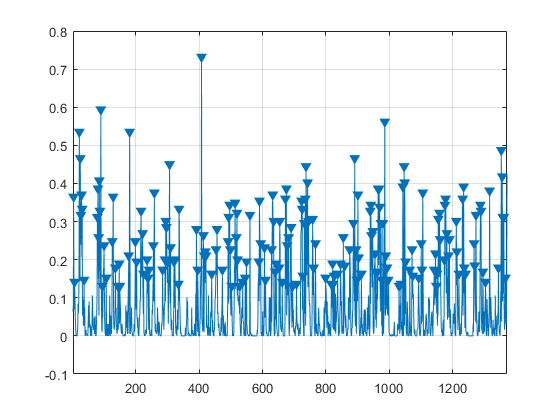

figure
findpeaks(synchrony_fraction,'MinPeakHeight',th);%Find the peaks that have an amplitude larger than threshold.

[peakValues, peakIdx] = findpeaks(synchrony_fraction,'MinPeakHeight',th);
%savefig('Synchrony_Peaks');

### Caculate Variabels

synchrony_peak_total_number = length(peakValues);
synchrony_fq = synchrony_peak_total_number / (end_time-start_time);
%synchrony_mean_fraction = mean (peakValues);

### Write Variables to Excel

writematrix(synchrony_fq,'Synchrony_freq.xlsx');
%save ('synchrony_fq.mat', 'synchrony_fq');
writematrix(peakValues,'Synchrony_peakValues.xlsx');
%save ('synchrony_peakValues.mat', 'peakValues');